## Bearbeiter A - Milchev, Mihail

Parameter, umgewandelt in $\mu s$ und $\mu m$:

clear;
clc;

% Die c variable ist global und von allen Funktionen verwendet.
% Vereinfacht die veränderung der Parameter bei Bedarf.
global c;
c = konstanten();

% Table
rownames = { 'Wert' };
disp(c)

        d: 0.300000000000000
        D: 0.300000000000000
      k_1: 1
      k_2: 0.010000000000000
      N_D: 1000
      S_L: 0.100000000000000
      S_R: 1000
    alpha: 10



table(c.d, c.D, c.k_1, c.k_2, c.N_D, c.S_L, c.S_R, c.alpha, 'RowNames', rownames)

ans = 1×8 table
            Var1    Var2    Var3    Var4    Var5    Var6    Var7    Var8
            ____    ____    ____    ____    ____    ____    ____    ____

    Wert    0.3     0.3      1      0.01    1000    0.1     1000     10 


## **2.1 Lineare stationäre Gleichung**

#### I. Schritt - Diskretisieren der Problemdomäne.

Im ersten Schritt wollen wir die Problemdomäne diskretisieren, indem wir das Interval $\left\lbrack a,b\right\rbrack$ in $N$ Teilintervalen teilen. Das Interval in unserem Fall ist $\left\lbrack 0,d\right\rbrack$. Daraus folgt:

$\left\lbrack 0,d\right\rbrack =\left\lbrack z_0 ,z_1 \right\rbrack \cup \left\lbrack z_1 ,z_2 \right\rbrack \cup \dots \cup \left\lbrack z_{N-1} ,z_N \right\rbrack$.

Dabei gilt für die Stützstellen: $0=z_0 <z_1 <\dots <z_{N-1} <z_N =d$. Wir nennen $h$ die Schrittgröße, und finden sie durch $h=\frac{\left(b-a\right)}{N}$ heraus. In unserem Fall ist Punkt $a=0$, also für die Schrittgröße gilt: 

$h=\frac{\left(d-0\right)}{N}=\frac{d}{N}$.

Den Wert für die jeweilige Stützstelle $z$ ist abhängig von der Schrittgröße $h$ und somit von der Anzahl der Teilintervalen $N$. Den genauen Wert kriegen wir durch:


$$z_i \;=i\cdot h,\;\;\;\;0\le i\le N$$
 

Es ist erkennbar, dass die Anzahl der Teilintervalen N die Schrittgröße verändert:

N = 5;
h = c.d/N;
disp(h);

   0.060000000000000



#### II. Schritt - Diskretisieren der Differenzialgleichungen.

In diesem Schritt wollen wir die Differenzialgleichungen sowohl am Rand, als auch im Inneren des Definitionsbereichs diskretisieren. Zur Übersichtlichkeit teilen wir das in **Teil a)** und **Teil b)** auf.

Darüber hinaus verwenden wir die Abkürzungen $u_i \;=\;u\left(z_i \right),s_i \;=\;s\left(z_i \right),\;0\le i\le N$ zur Bezeichnung der Approximationen der Lösungen von $u\left(z\right)\;\textrm{und}\;s\left(z\right)$. Die Abkürzungen $u_i \;$bzw. $s_i$ werden verwendet, da die Funktionen $u\left(z\right)$ und $s\left(z\right)$ uns nicht bekannt sind. Daher können wir keine analytische Lösung ermitteln, sonder nur die numerische Approximationen $u_i \;$bzw. $s_i$ beider Funktionen.

#### a) Diskretisierung der inneren Stützpunkten $z_1 ,\dots ,z_{N-1}$.

Für die Annäherung der Ableitungen der Differenzialgleichung verwenden wir die zentrale Differenzenquotienten für die erste und zweite Ableitung:

$\begin{array}{l}
u\prime \left(z_i \right)\approx \frac{u_{i+1} -u_{i-1} }{2\cdot h}\;+\;O\left(h^2 \right)\\
u\prime \prime \left(z_i \right)\approx \frac{u_{i+1} -2\cdot u_i +\;u_{i-1} }{h^2 }\;+\;O\left(h^2 \right)
\end{array}$.

Bei Ersetzen in Gleichung (6):

$\begin{array}{l}
s_i \;=-D\cdot u\prime \prime \left(z_i \right)+\;k\cdot u_i \\
=-D\cdot \left(\frac{u_{i+1} -2\cdot u_i +\;u_{i-1} }{h^2 }\right)+k\cdot u_i \\
=-\frac{D}{h^2 }\cdot u_{i-1} +\left(\frac{2\cdot D}{h^2 }+k\right)\cdot u_i -\frac{D}{h^2 }u_{i+1} 
\end{array}$,

wobei wir den Restterm für den Fehler $O\left(h^2 \right)\;$vernachlassigen können bei genügend großer Anzahl Teilintervalen $N$. Mit steigendem $N$ wird der Term $h$ immer kleiner, und das Quadrat davon sogar noch kleiner. Somit nehmen wir an, dass der Fehler $O\left(h^2 \right)\;$vernachlässigbar ist.

Wir betrachten 4 Fälle für den Wert von $z$:

#### Fall 1: i = 0


$$s_0 \;=-\frac{D}{h^2 }\cdot u_{-1} +\left(\frac{2\cdot D}{h^2 }+k\right)\cdot u_0 -\frac{D}{h^2 }{\cdot \;u}_1$$
 

#### Fall 2: i = 1


$$s_1 \;=-\frac{D}{h^2 }\cdot u_0 +\left(\frac{2\cdot D}{h^2 }+k\right)\cdot u_1 -\frac{D}{h^2 }{\cdot \;u}_2$$


#### Fall 3: i = N - 1


$$s_{N-1} \;=-\frac{D}{h^2 }\cdot u_{N-2} +\left(\frac{2\cdot D}{h^2 }+k\right)\cdot u_{N-1} -\frac{D}{h^2 }{\cdot \;u}_N$$


#### Fall 4: i = N


$$s_N \;=-\frac{D}{h^2 }\cdot u_{N-1} +\left(\frac{2\cdot D}{h^2 }+k\right)\cdot u_N -\frac{D}{h^2 }{\cdot \;u}_{N+1}$$


Die Gleichungen bei $i=0$, bzw. $i=N$ beinhalten die Terme $u_{-1}$ und $u_{N+1}$ respektiv. Um sie zu eliminieren diskretisieren wir im folgenden Teil die Randbedingungen.

#### b) Diskretisierung der Stützpunkten $u\left(z_0 \right)$ und $u\left(z_{N-1} \right)$.

In diesem Teil approximieren wir die ersten Ableitungen der Randbedingungen durch

$\begin{array}{l}
u\prime \left(0\right)\approx \frac{u_1 -u_{-1} }{2\cdot h}\\
u\prime \left(d\right)\approx \frac{u_{N+1} -u_{N-1} }{2\cdot h}
\end{array}$.

Bei Ersetzen in den Gleichungen für die Randbedingungen von Gleichung (5) ergibt sich:

#### b.1) Für $u\prime \left(0\right)$


$$\frac{u_1 -u_{-1} }{2\cdot h}=\frac{S_L }{D}\cdot u_0$$


Aufgelöst nach $u_{-1}$:


$$u_{-1} =u_1 -\frac{2\cdot h\cdot S_L }{D}\cdot u_0$$


#### b.2) Für $u\prime \left(d\right)$


$$\frac{u_{N+1} -u_{N-1} }{2\cdot h}=-\frac{S_R }{D}\cdot u_N$$


Aufgelöst nach $u_{N+1}$


$$u_{N+1} =u_{N-1} -\frac{2\cdot h\cdot S_R }{D}\cdot u_N$$


Nun können die Terme $u_{-1}$ und $u_{N+1}$ von den Gleichungungen für die innere Stützpunkte eliminiert werden:

#### Fall 1: i = 0

$s_0 \;=-\frac{D}{h^2 }\cdot u_{-1} +\left(\frac{2\cdot D}{h^2 }+k\right)\cdot u_0 -\frac{D}{h^2 }{\cdot u}_1$, mit $u_{-1} =u_1 -\frac{2\cdot h\cdot S_L }{D}\cdot u_0$ 


$$\begin{array}{l}
s_0 \;=-\frac{D}{h^2 }\cdot \left(u_1 -\frac{2\cdot h\cdot S_L }{D}\cdot u_0 \right)+\left(\frac{2\cdot D}{h^2 }+k\right)\cdot u_0 -\frac{D}{h^2 }{\cdot \;u}_1 \\
=\left(\frac{2\cdot S_L }{h}+\frac{2\cdot D}{h^2 }+k\right)\cdot u_0 -\frac{2\cdot D}{h^2 }{\cdot \;u}_1 
\end{array}$$


#### Fall 4: i = N

$s_N \;=-\frac{D}{h^2 }\cdot u_{N-1} +\left(\frac{2\cdot D}{h^2 }+k\right)\cdot u_N -\frac{D}{h^2 }{\cdot \;u}_{N+1}$, mit $u_{N+1} =u_{N-1} -\frac{2\cdot h\cdot S_R }{D}\cdot u_N$


$$\begin{array}{l}
s_N \;=-\frac{D}{h^2 }\cdot u_{N-1} +\left(\frac{2\cdot D}{h^2 }+k\right)\cdot u_N -\frac{D}{h^2 }\cdot \left(u_{N-1} -\frac{2\cdot h\cdot S_R }{D}\cdot u_N \right)\\
=-\frac{2\cdot D}{h^2 }{\cdot \;u}_{N-1} +\left(\frac{2\cdot S_R }{h}+\frac{2\cdot D}{h^2 }+k\right)\cdot u_N 
\end{array}$$


Nun sieht das lineare Gleichungssystem finiter Differenzen, analog zu Gleichung (8.133) in Quelle [1], folgend aus:

$A\cdot u=s$,

mit:

- $A$ die Finite Differenzen Matrix, 

- $u$ der Vektor der Unbekannten ${\left\lbrack \begin{array}{ccccc}
u_0  & u_1  & \dots  & u_{N-1}  & u_N 
\end{array}\right\rbrack }^T$

- $s$ der Vektor der numerischen Lösungen ${\left\lbrack \begin{array}{ccccc}
s_0  & s_1  & \dots  & s_{N-1}  & s_N 
\end{array}\right\rbrack }^T$.

Unter Beachtung der Randwerten, sieht die Matrix nach Einsetzten den entsprechenden Werten so aus:


$$\left\lbrack \begin{array}{ccccc}
\left(\frac{2\cdot S_L }{h}+\frac{2\cdot D}{h^2 }+k\right) & -\frac{2\cdot D}{h^2 } & \; & \; & \;\\
-\frac{D}{h^2 } & \left(\frac{2\cdot D}{h^2 }+k\right) & -\frac{D}{h^2 } & \; & \;\\
\; & \ddots  & \ddots  & \ddots  & \;\\
\; & \; & -\frac{D}{h^2 } & \left(\frac{2\cdot D}{h^2 }+k\right) & -\frac{D}{h^2 }\\
\; & \; & \; & -\frac{2\cdot D}{h^2 } & \left(\frac{2\cdot S_R }{h}+\frac{2\cdot D}{h^2 }+k\right)
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
u_0 \\
u_1 \\
\dots \\
u_{N-1} \\
u_N 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
s_0 \\
s_1 \\
\dots \\
s_{N-1} \\
s_N 
\end{array}\right\rbrack$$


A = fd_lin_matrix(N);
% A ist dünnbesetzt. full(A) zeigt die "normale" Matrix
disp(full(A));

   1.0e+04 *

  Columns 1 through 3

   0.018100000000000  -0.016666666666667                   0
  -0.008333333333333   0.017766666666667  -0.008333333333333
                   0  -0.008333333333333   0.017766666666667
                   0                   0  -0.008333333333333
                   0                   0                   0
                   0                   0                   0

  Columns 4 through 6

                   0                   0                   0
                   0                   0                   0
  -0.008333333333333                   0                   0
   0.017766666666667  -0.008333333333333                   0
  -0.008333333333333   0.017766666666667  -0.008333333333333
                   0  -0.016666666666667   3.351100000000000



### 2.1.7 - Testen der Routine

Zum Testen der Routine von Aufgabe 2.1.6 (stationaer_lin()), wird die folgende Funktion verwendet:

$u\left(z\right)=2\cdot z+1$.

Nun ist uns die Testfunktion $u\left(z\right)$ bekannt und damit die Werte am Rand des Definitionsbereiches. Wenn wir die Randbedingungen betrachten, können wir nach $S_L$ bzw. $S_R$ auflösen und die neue Werte für beide Konstanten berechnen.

Die erste Ableitung der Funktion lautet in diesem Fall 


$$u^{\prime } \left(z\right)=2$$


Und die zweite Ableitung:


$$u^{\prime \prime } \left(z\right)=0$$


#### I. Randbedingung für Funktion $u\left(z\right)$an Stelle $u\left(0\right)$, bei Einsetzen von $u\left(0\right)=2\cdot 0+1$, und  aufgelöst nach $S_L$:

$S_L =D\cdot \frac{u^{\prime } \left(0\right)}{u\left(0\right)}=D\cdot \frac{2}{1}=D\cdot 2$.

#### II. Randbedingung für Funktion $u\left(z\right)$an Stelle $u\left(d\right)$, bei Einsetzen von $u\left(d\right)=2\cdot d+1$, und  aufgelöst nach $S_R$:

$S_R =-D\cdot \frac{u^{\prime } \left(d\right)}{u\left(d\right)}=-D\cdot \frac{2}{\left(2\cdot d+1\right)}$ .

Gleichung (6) kann entsprechend umgeformt werden:


$$\begin{array}{l}
s\left(z\right)=-D\cdot u^{\prime \prime } \left(z\right)+k\cdot u\left(z\right)\\
=-D\cdot 0+k\cdot \left(2\cdot z+1\right)
\end{array}$$


% Anzahl der Teilintervalle
N = 5;

% 2.1.7 - Testen
c.d = 1.0;
c.D = 0.5;
c.S_L = 2 * c.D;
c.S_R = -c.D * (2/(2*c.d + 1));

[z_lin, u_lin] = stationaer_lin(@s_lin, N);

disp(z_lin);

                   0
   0.200000000000000
   0.400000000000000
   0.600000000000000
   0.800000000000000
   1.000000000000000



disp(u_lin);

   1.000000000000000
   1.399999999999999
   1.799999999999999
   2.199999999999999
   2.599999999999999
   3.000000000000000



% Konstanten "erfrischen" nach Ende von Aufg. 2.1.6
c = konstanten();

### 2.1.8 - Experimentelle Bestimmung eines geeigneten Wertes N

Hier wird eine Folge von Werten für die Konstante $S_L$ in der Funktion $s\left(z\right)=S_L \cdot e^{-\alpha z}$ vorgegeben. Deren Werte werden zwischen ${10}^2$ bis${10}^4 \;\frac{1}{\mu m^3 \;\mu s}$ variiert. 

Als Erstes werden die Vektoren $z$ und $u$ in Matrizen gespeichert. Das dient dazu, den relativen Fehler im nächsten Schritt zu ermitteln. 

bei Variierung von 	der Anzahl der Teilinten $N$.

global S_0;
S_0 = 10^2; % 10^2..4 * 1/(um^3 * us)

N_initial = 5;
N_final = 500;

len_cols = length(N_initial:5:N_final);
len_rows = N_final + 1;

% Matrix of Nodes
z_matrix = zeros( len_rows, len_cols );
% Matrix of node values
u_matrix = zeros( len_rows, len_cols );
% Matrix of relative errors
err_rel_mat = zeros( len_rows, len_cols );

index = 0;

% Increment N by 5 every time
for N = N_initial:5:N_final
    [z_lin, u_lin] = stationaer_lin(@s_experimentell, N);
    
    % index beginnt von 1
    index = index + 1;
    
    % u und z Vektoren in Matrizen speichern
    u_matrix(1:length(u_lin), index) = u_lin;
    z_matrix(1:length(z_lin), index) = z_lin;
end

% Loop through columns
for cols = 2:len_cols
    
    % Loop through rows 
    for rows = 2:len_rows
        
        % find element at (row, column) in entire adjacent (next) column.
        [row, col] = find( z_matrix(rows-1, cols-1) == z_matrix(:, cols) );
        
        % If row is not empty, it means there was a match
        if ~isempty(row)
            % Take only the first value in the row array, as there are many 0s
            % after value 1.0, which are irrelevant, even though they match.
            err_rel_mat(rows - 1, cols - 1) = abs( u_matrix(row(1), cols) - u_matrix(rows-1, cols-1) );
        
            % d is the last value in the z_matrix always.
            % Once d is reached, you can break the inner loop
            % in order to move over to the next column
            if z_matrix(row(1), cols) == c.d
                break;
            end %if
        
        end %if
     
    end %for 
    
end %for

% Index des relativen Fehlers ermitteln, wo rel_err < 1 promil ist.
% rel_err_ind + 1 because the relative error is calculated from
% the next number of N elements substracted from the N elements
% used at the current step?
rel_err_ind = ( find(max(err_rel_mat(:,1:end-1)) < 0.001, 1) + 1 );

if ~isempty(rel_err_ind)
    N_vals = N_initial:5:N_final;
    N_best = N_vals(rel_err_ind);
    disp(N_best);
else
    disp("No relative error under 1 promil found. Try Increasing N!");
end

    40



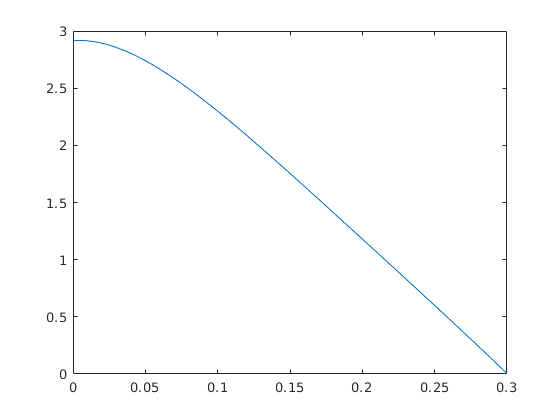


% We do not want to include any 0s other than z_matrix(1) in the plot.
% Find first index where vector has value 0.
% Start from 2 because z_matrix(1) is always 0
% Find only 1 (basically the first Treffer) zero element (see z_matrix and
% it will become immediately clear why we search for the first zero
% element. It indicates the length of the vector! )
n_best_vec_len_z = find(z_matrix(2:end, rel_err_ind) == 0, 1);
n_best_vec_len_u = find(u_matrix(2:end, rel_err_ind) == 0, 1);

plot(z_matrix(1:n_best_vec_len_z, rel_err_ind), u_matrix(1:n_best_vec_len_u, rel_err_ind));

% Konstanten "erfrischen" für nächste Aufgabe - 2.2
c = konstanten();

## **2.2 Nichtlineare stationäre Gleichung**

Als erstes leiten wir die nichtlinearen Gleichungen für die Werte des Vektors $u$ von Gleichung (4) in der Hausarbeit:

$D\cdot u\prime \prime \left(z_i \right)-\left(k_1 +k_2 \cdot N_D \right)\cdot u\left(z_i \right)\;-k_2 \cdot {u\left(z_i \right)}^2 =-s\left(z_i \right)$.

Ähnlich zur Aufgabe 2.1.a) verwenden wir hier zur Annäherung der Ableitungen $u\prime \left(z_i \right)$ und $u\prime \prime \left(z_i \right)$ die zentrale Differenzenquotienten der ersten und zweiten Ableitungen. Darüber hinaus werden zur Bezeichnung der Approximationen der Lösungen von $u\left(z\right)\;\textrm{und}\;s\left(z\right)$ wieder die Abkürzungen $u_i \;=\;u\left(z_i \right),s_i \;=\;s\left(z_i \right),\;0\le i\le N$ verwendet. Daraus ergibt sich folgende Gleichung:


$$\begin{array}{l}
D\cdot \left(\frac{u_{i+1} +2\cdot u_i +u_{i-1} }{h^2 }\right)+\;O\left(h^2 \right)-\left(k_1 +k_2 \cdot N_D \right)\cdot u_i \;-k_2 \cdot {u_i }^2 =-s\left(z_i \right)\\
\Rightarrow \frac{D}{h^2 }\cdot u_{i-1} -\left(\frac{2\cdot D}{h^2 }+k_1 +k_2 \cdot N_D \right)\cdot u_i -k_2 \cdot {u_i }^2 +\frac{D}{h^2 }\cdot u_{i+1} +\;O\left(h^2 \right)=-s\left(z_i \right)
\end{array}$$


Wie bei der vorherigen Aufgabe vernachlassigen w den Restterm $O\left(h^2 \right)\;$und betrachten 4 Fälle für den Wert von $i$:

#### Fall 1: i = 0


$$\frac{D}{h^2 }\cdot u_{-1} -\left(\frac{2\cdot D}{h^2 }+k_1 +k_2 \cdot N_D \right)\cdot u_0 -k_2 \cdot {u_0 }^2 +\frac{D}{h^2 }u_1 =-s_0$$
 

#### Fall 2: i = 1


$$\frac{D}{h^2 }\cdot u_0 -\left(\frac{2\cdot D}{h^2 }+k_1 +k_2 \cdot N_D \right)\cdot u_1 -k_2 \cdot {u_1 }^2 +\frac{D}{h^2 }u_2 =-s_0$$


#### Fall 3: i = N - 1


$$\frac{D}{h^2 }\cdot u_{N-2} -\left(\frac{2\cdot D}{h^2 }+k_1 +k_2 \cdot N_D \right)\cdot u_{N-1} -k_2 \cdot {u_{N-1} }^2 +\frac{D}{h^2 }u_N =-s_{N-1}$$


#### Fall 4: i = N


$$\frac{D}{h^2 }\cdot u_{N-1} -\left(\frac{2\cdot D}{h^2 }+k_1 +k_2 \cdot N_D \right)\cdot u_N -k_2 \cdot {u_N }^2 +\frac{D}{h^2 }u_{N+1} =-s_N$$


Die Gleichungen bei $i=0$, bzw. $i=N$ beinhalten die Terme $u_{-1}$ und $u_{N+1}$ respektiv. Um sie zu eliminieren setzen wir die nach $u_{-1}$ bzw. $u_{N+1}$  aufgelösten diskretisierten Randbedingungen ein.

#### Fall 1: i = 0

 $\frac{D}{h^2 }\cdot u_{-1} -\left(\frac{2\cdot D}{h^2 }+k_1 +k_2 \cdot N_D \right)\cdot u_0 -k_2 \cdot {u_0 }^2 +\frac{D}{h^2 }u_1 =-s_0$, mit $u_{-1} =u_1 -\frac{2\cdot h\cdot S_L }{D}\cdot u_0$ 


$$\Rightarrow -\left(\frac{2\cdot S_L }{h}+\frac{2\cdot D}{h^2 }+k_1 +k_2 \cdot N_D \right)\cdot u_0 -k_2 \cdot {u_0 }^2 +\frac{2\cdot D}{h^2 }\cdot u_1 =-s_0 \;\;$$


#### Fall 4: i = N

$\frac{D}{h^2 }\cdot u_{N-1} -\left(\frac{2\cdot D}{h^2 }+k_1 +k_2 \cdot N_D \right)\cdot u_N -k_2 \cdot {u_N }^2 +\frac{D}{h^2 }u_{N+1} =-s_N$, mit $u_{N+1} =u_{N-1} -\frac{2\cdot h\cdot S_R }{D}\cdot u_N$


$$\Rightarrow \frac{2\cdot D}{h^2 }\cdot u_{N-1} -\left(\frac{2\cdot S_R }{h}+\frac{2\cdot D}{h^2 }+k_1 +k_2 \cdot N_D \right)\cdot u_N -k_2 \cdot {u_N }^2 =-s_N \;\;$$


Um die Gleichungen als Vektor aufstellen zu können, müssen wir nach dem entsprechenden $u_i$ auflösen.?????????????????????

Der Vektor u von Größe N wird abgebildet auf f(u) und ist gleich s - das Ergebnis nach der Anwendung der Funktionsvorschrift. Nun sieht das System mit dem Vektor finiter Differenzen folgend aus:

(F(u) ist vektorwertig. Die Größe der J-Matrix in fd_nonlin_jac() unterstützt diese Aussage auch )

$F\left(u\right)=b$,

mit:

- $F$ der Vektor finiter Differenzen, 

- $u$ der Vektor der Unbekannten numerischen Lösungen ${\left\lbrack \begin{array}{ccccc}
u_0  & u_1  & \dots  & u_{N-1}  & u_N 
\end{array}\right\rbrack }^T$

- $s$ der Vektor der rechten Seite ${\left\lbrack \begin{array}{ccccc}
s_0  & s_1  & \dots  & s_{N-1}  & s_N 
\end{array}\right\rbrack }^T$.

Unter Beachtung der Randwerten, bekommen wir für den Vektor nach Einsetzten den entsprechenden Werten:


$$F\left\lbrack \begin{array}{c}
u_0 \\
u_1 \\
\cdots \\
u_{N-1} \\
u_N 
\end{array}\right\rbrack =\;\left(\begin{array}{c}
-\left(\frac{2\cdot S_L }{h}+\frac{2\cdot D}{h^2 }+k_1 +k_2 \cdot N_D \right)\cdot u_0 -k_2 \cdot {u_0 }^2 +\frac{2\cdot D}{h^2 }\cdot u_1 \\
\frac{D}{h^2 }\cdot u_0 -\left(\frac{2\cdot D}{h^2 }+k_1 +k_2 \cdot N_D \right)\cdot u_1 -k_2 \cdot {u_1 }^2 +\frac{D}{h^2 }u_2 \\
\dots \\
\frac{D}{h^2 }\cdot u_{N-2} -\left(\frac{2\cdot D}{h^2 }+k_1 +k_2 \cdot N_D \right)\cdot u_{N-1} -k_2 \cdot {u_{N-1} }^2 +\frac{D}{h^2 }u_N \\
\frac{2\cdot D}{h^2 }\cdot u_{N-1} -\left(\frac{2\cdot S_R }{h}+\frac{2\cdot D}{h^2 }+k_1 +k_2 \cdot N_D \right)\cdot u_N -k_2 \cdot {u_N }^2 
\end{array}\right)$$


#### Berechnung der Jacob-Matrix $J_F$ von $F$

Die Jacobi-Matrix für den Vektor F ist definiert als:

$J_F \left(u_0 ,u_1 ,\dots ,u_{N-1} ,u_N \right)=\left\lbrack \begin{array}{cccc}
\frac{\partial f_0 }{\partial u_0 } & \frac{\partial f_0 }{\partial u_1 } & \dots  & \frac{\partial f_0 }{\partial u_N }\\
\frac{\partial f_1 }{\partial u_0 } & \frac{\partial f_1 }{\partial u_1 } & \dots  & \frac{\partial f_1 }{\partial u_N }\\
\vdots  & \vdots  & \ddots  & \vdots \\
\frac{\partial f_N }{\partial u_0 } & \frac{\partial f_N }{\partial u_1 } & \dots  & \frac{\partial f_N }{\partial u_N }
\end{array}\right\rbrack$,

mit partieller Ableitungen der Funktionen am Rand des Definitionsbereiches in Zeile 1 und Zeile N+1, 


$$J_F \left(u_0 ,u_1 ,\dots ,u_{N-1} ,u_N \right)=\left\lbrack \begin{array}{cccc}
-\left(\frac{2\cdot S_L }{h}+\frac{2\cdot D}{h^2 }+k_1 +k_2 \cdot N_D \right)-{2\cdot \;k}_2 \cdot u_0  & \frac{2\cdot D}{h^2 } & \; & \;\\
\frac{D}{h^2 } & -\left(\frac{2\cdot D}{h^2 }+k_1 +k_2 \cdot N_D \right)-2\cdot k_2 \cdot u_1  & \frac{D}{h^2 }\; & \;\\
\; & \ddots  & \ddots  & \ddots \;\\
\; & \frac{D}{h^2 } & -\left(\frac{2\cdot D}{h^2 }+k_1 +k_2 \cdot N_D \right)-2\cdot k_2 \cdot u_{N-1}  & \frac{D}{h^2 }\\
\; & \; & \frac{2\cdot D}{h^2 } & -\left(\frac{2\cdot S_R }{h}+\frac{2\cdot D}{h^2 }+k_1 +k_2 \cdot N_D \right)-{2\cdot \;k}_2 \cdot u_N 
\end{array}\right\rbrack$$


### 2.2.6 - Testen der Routine

Zum Testen der Routine von Aufgabe 2.1.5 (stationaer_nonlin()), wird die folgende Funktion verwendet:

$u\left(z\right)=z^2 +z+2$.

Nun ist uns die Testfunktion $u\left(z\right)$ bekannt und damit die Werte am Rand des Definitionsbereiches. Wenn wir die Randbedingungen betrachten, können wir nach $S_L$ bzw. $S_R$ auflösen und die neue Werte für beide Konstanten berechnen.

Die erste Ableitung der Funktion $u\left(z\right)$lautet:


$$u^{\prime } \left(z\right)=2\cdot z+1$$


Die zweite Abletung:


$$u^{\prime \prime } \left(z\right)=2$$


#### I. Randbedingung für Funktion $u\left(z\right)$an Stelle $u\left(0\right)$, aufgelöst nach $S_L$:

$S_L =D\cdot \frac{u^{\prime } \left(0\right)}{u\left(0\right)}=\frac{1}{2}\cdot D$.

#### II. Randbedingung für Funktion $u\left(z\right)$an Stelle $u\left(d\right)$, aufgelöst nach $S_R$:

$S_R =-D\cdot \frac{u^{\prime } \left(d\right)}{u\left(d\right)}=-D\cdot \frac{1}{\left(d^2 +\;d+2\right)}$ .

Die Funktion $s\left(z\right)$ lautet in diesem Fall:


$$\begin{array}{l}
s\left(z\right)=-D\cdot u\prime \prime \left(z_i \right)+\left(k_1 +k_2 \cdot N_D \right)\cdot u\left(z_i \right)+k_2 \cdot {u\left(z_i \right)}^2 \\
\;\;\;\;\;\;\;\;=-D\cdot 2+\left(k_1 +k_2 \cdot N_D \right)\cdot \left(z^2 +z+2\right)+k_2 \cdot {\left(z^2 +z+2\right)}^2 \;
\end{array}$$


% Anzahl der Teilintervalle
N = 500;

% 2.2.6 - Testen
c.d = 1.0;
c.D = 0.5;
c.S_L = (1/2) * c.D;
c.S_R = (-1) * ( c.D * (1/( (c.d*c.d) + c.d + 2)) );

tol = 0.05;
nmax = 40;

[z_nlin, u_nlin] = stationaer_nonlin(@s_nonlin, N, tol, nmax);

disp(z_nlin);

                   0
   0.002000000000000
   0.004000000000000
   0.006000000000000
   0.008000000000000
   0.010000000000000
   0.012000000000000
   0.014000000000000
   0.016000000000000
   0.018000000000000
   0.020000000000000
   0.022000000000000
   0.024000000000000
   0.026000000000000
   0.028000000000000
   0.030000000000000
   0.032000000000000
   0.034000000000000
   0.036000000000000
   0.038000000000000
   0.040000000000000
   0.042000000000000
   0.044000000000000
   0.046000000000000
   0.048000000000000
   0.050000000000000
   0.052000000000000
   0.054000000000000
   0.056000000000000
   0.058000000000000
   0.060000000000000
   0.062000000000000
   0.064000000000000
   0.066000000000000
   0.068000000000000
   0.070000000000000
   0.072000000000000
   0.074000000000000
   0.076000000000000
   0.078000000000000
   0.080000000000000
   0.082000000000000
   0.084000000000000
   0.086000000000000
   0.088000000000000
   0.090000000000000
   0.092000000000000
   0.09400000

disp(u_nlin);

   1.992571318718911
   1.994567561989272
   1.996571148475468
   1.998582077432027
   2.000600348055392
   2.002625959483843
   2.004658910797427
   2.006699201017871
   2.008746829108497
   2.010801793974130
   2.012864094460999
   2.014933729356638
   2.017010697389773
   2.019094997230211
   2.021186627488726
   2.023285586716928
   2.025391873407143
   2.027505485992270
   2.029626422845648
   2.031754682280911
   2.033890262551835
   2.036033161852187
   2.038183378315561
   2.040340910015216
   2.042505754963903
   2.044677911113688
   2.046857376355772
   2.049044148520302
   2.051238225376181
   2.053439604630869
   2.055648283930179
   2.057864260858066
   2.060087532936419
   2.062318097624837
   2.064555952320404
   2.066801094357458
   2.069053521007356
   2.071313229478231
   2.073580216914745
   2.075854480397835
   2.078136016944458
   2.080424823507319
   2.082720896974608
   2.085024234169722
   2.087334831850983
   2.089652686711350
   2.091977795378126
   2.09431015

% Konstanten "erfrischen" nach Ende von Aufg. 2.2.6
c = konstanten();

### 2.1.8 - Experimentelle Bestimmung eines geeigneten Wertes N

Hier wird eine Folge von Werten für die Konstante $S_L$ in der Funktion $s\left(z\right)=S_L \cdot e^{-\alpha z}$ vorgegeben. Deren Werte werden zwischen ${10}^2$ bis${10}^4 \;\frac{1}{\mu m^3 \;\mu s}$ variiert. 

Als Erstes werden die Vektoren $z$ und $u$ in Matrizen gespeichert. Das dient dazu, den relativen Fehler im nächsten Schritt zu ermitteln. 

bei Variierung von 	der Anzahl der Teilinten $N$. 

% Zum Vergleich beider Lösungen sollen die S_0, N_initial und N_final diesselbe bleiben wie
% in stationaer_lin()


% Matrix of Nodes
z_matrix_nlin = zeros( len_rows, len_cols );
% Matrix of node values
u_matrix_nlin = zeros( len_rows, len_cols );
% Matrix of relative errors
err_rel_nlin = zeros( len_rows, len_cols );

index = 0;

% Increment N by 5 every time
for N = N_initial:5:N_final
    [z_nlin, u_nlin] = stationaer_nonlin(@s_experimentell, N, tol, nmax);
    
    % index beginnt von 1
    index = index + 1;
    
    % u und z Vektoren in Matrizen speichern
    u_matrix_nlin(1:length(u_nlin), index) = u_nlin;
    z_matrix_nlin(1:length(z_nlin), index) = z_nlin;
end

% Loop through columns
for cols = 2:len_cols
    
    % Loop through rows 
    for rows = 2:len_rows
        
        % find element at (row, column) in entire adjacent (next) column.
        [row, col] = find( z_matrix_nlin(rows-1, cols-1) == z_matrix_nlin(:, cols) );
        
        % If row is not empty, it means there was a match
        if ~isempty(row)
            % Take only the first value in the row array, as there are many 0s
            % after value 1.0, which are irrelevant, even though they match.
            err_rel_nlin(rows - 1, cols - 1) = abs( u_matrix_nlin(row(1), cols) - u_matrix_nlin(rows-1, cols-1) );
        
            % d is the last value in the z_matrix always.
            % Once d is reached, you can break the inner loop
            % in order to move over to the next column
            if z_matrix_nlin(row(1), cols) == c.d
                break;
            end %if
        
        end %if
     
    end %for 
    
end %for

% Index des relativen Fehlers ermitteln, wo rel_err < 1promil ist
% rel_err_ind + 1 because the relative error is calculated from
% the next number of N elements substracted from the N elements
% used at the current step?
rel_err_ind_nlin = ( find(max(err_rel_nlin(:,1:end-1)) < 0.001, 1) + 1 );

if ~isempty(rel_err_ind_nlin)
    N_vals = N_initial:5:N_final;
    N_best_nlin = N_vals(rel_err_ind_nlin);
    disp(N_best_nlin);
else
    disp("No relative error under 1 promil found. Try Increasing N!");
end

   140



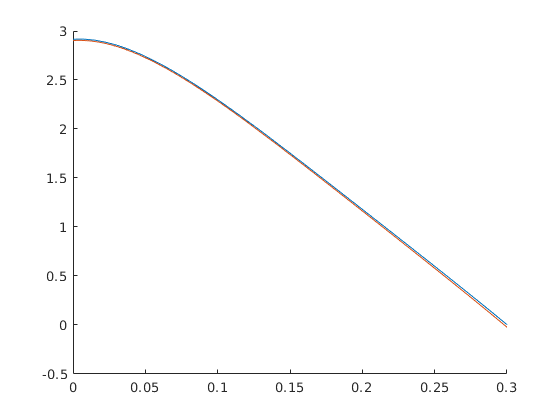


% We do not want to include any 0s other than z_matrix(1) in the plot.
% Find first index where vector has value 0.
% Start from 2 because z_matrix(1) is always 0
% Find only 1 (basically the first Treffer) zero element
n_best_vec_len_z_nlin = find(z_matrix_nlin(2:end, rel_err_ind_nlin) == 0, 1);
n_best_vec_len_u_nlin = find(u_matrix_nlin(2:end, rel_err_ind_nlin) == 0, 1);

figure;
hold on;
plot(z_matrix(1:n_best_vec_len_z, rel_err_ind), u_matrix(1:n_best_vec_len_u, rel_err_ind));
plot(z_matrix_nlin(1:n_best_vec_len_z_nlin, rel_err_ind_nlin), u_matrix_nlin(1:n_best_vec_len_u_nlin, rel_err_ind_nlin));
hold off;

$\matrix{
\ z_i            & e^z         & u_i (N=5)     & u_i (N=10)    & u_i (N=20)
\cr
0.00                & 1.0000                     &1.0001     &1.0000     &1.0000
\cr
0.06                & 1.0618                     &1.0619     &1.0618     &1.0618
                \cr
0.12                & 1.1275                    & 1.1275     &1.1275     &1.1275
                                \cr
0.18        & 1.1972                    &1.1972       &1.1972    &1.1972
\cr
0.24         &1.2712               &  1.2712     &1.2712     &1.2712
\cr
0.30          & 1.3499           &1.3498         &1.3498      & 1.3499
}$ - Compareeee

## **4 Zeitaufgelöste Simulation - Bearbeiter A**

Für die Simulation des Systems ist als Erstes nötig sie in der Form


$$u^{\prime \;=\;\;} F\left(t,\;u\right)$$


zu formulieren, mit:

- $u^{\prime \;}$der Vektor der numerischen Lösungen${\left\lbrack \begin{array}{ccccc}
u_0^{\prime }  & u_1^{\prime }  & \dots  & u_{N-1}^{\prime }  & u_N^{\prime } 
\end{array}\right\rbrack }^T$, TODO.......................................

- $F$der Vektor finiter Differenzen, 

- $t$ die Zeitschritte, und

- $u$ der Vektor der Unbekannten ${\left\lbrack \begin{array}{ccccc}
u_0  & u_1  & \dots  & u_{N-1}  & u_N 
\end{array}\right\rbrack }^T$.

Unter Beachtung der Randwerten, bekommen wir für den Vektor nach Einsetzten den entsprechenden Werten:


$$\left\lbrack \begin{array}{c}
u_0^{\prime } \\
u_1^{\prime } \\
\dots \\
u_{N-1}^{\prime } \\
u_N^{\prime } 
\end{array}\right\rbrack \;=\;F\left(\begin{array}{c}
-\left(\frac{2\cdot S_L }{h}+\frac{2\cdot D}{h^2 }+k_1 +k_2 \cdot N_D \right)\cdot u_0 \left(t\right)-k_2 \cdot {u_0 }^2 \left(t\right)+\frac{2\cdot D}{h^2 }\cdot u_1 \left(t\right)+s_0 \left(t\right)\\
\frac{D}{h^2 }\cdot u_0 \left(t\right)-\left(\frac{2\cdot D}{h^2 }+k_1 +k_2 \cdot N_D \right)\cdot u_1 \left(t\right)-k_2 \cdot {u_1 }^2 \left(t\right)+\frac{D}{h^2 }u_2 +s_1 \left(t\right)\\
\dots \\
\frac{D}{h^2 }\cdot u_{N-2} \left(t\right)-\left(\frac{2\cdot D}{h^2 }+k_1 +k_2 \cdot N_D \right)\cdot u_{N-1} \left(t\right)-k_2 \cdot {u_{N-1} }^2 \left(t\right)+\frac{D}{h^2 }u_N \left(t\right)+s_{N-1} \left(t\right)\\
\frac{2\cdot D}{h^2 }\cdot u_{N-1} \left(t\right)-\left(\frac{2\cdot S_R }{h}+\frac{2\cdot D}{h^2 }+k_1 +k_2 \cdot N_D \right)\cdot u_N \left(t\right)-k_2 \cdot {u_N }^2 \left(t\right)+s_N \left(t\right)
\end{array}\right)$$


#### Berechnung der Jacob-Matrix $J_F$ von $F$

Die Jacobi-Matrix für den Vektor F, in Abhängigkeit von den Zeitschritten t ist definiert als:

$J_F \left(t,u\right)=\left\lbrack \begin{array}{cccc}
\frac{\partial F}{\partial u_0 }\left(t_0 \right) & \frac{\partial F}{\partial u_1 }\left(t_0 \right) & \dots  & \frac{\partial F}{\partial u_N }\left(t_0 \right)\\
\frac{\partial F}{\partial u_0 }\left(t_1 \right) & \frac{\partial F}{\partial u_1 }\left(t_1 \right) & \dots  & \frac{\partial F}{\partial u_N }\left(t_1 \right)\\
\vdots  & \vdots  & \ddots  & \vdots \\
\frac{\partial F}{\partial u_0 }\left(t_N \right) & \frac{\partial F}{\partial u_1 }\left(t_N \right) & \dots  & \frac{\partial F}{\partial u_N }\left(t_N \right)
\end{array}\right\rbrack$,

mit partieller Ableitungen der Funktionen am Rand des Definitionsbereiches in Zeile 1 und Zeile N+1, 


$$J_F \left(u_0 ,u_1 ,\dots ,u_{N-1} ,u_N \right)=\left\lbrack \begin{array}{cccc}
-\left(\frac{2\cdot S_L }{h}+\frac{2\cdot D}{h^2 }+k_1 +k_2 \cdot N_D \right)-{2\cdot \;k}_2 \cdot u_0 \left(t_0 \right) & \frac{2\cdot D}{h^2 } & \; & \;\\
\frac{D}{h^2 } & -\left(\frac{2\cdot D}{h^2 }+k_1 +k_2 \cdot N_D \right)-2\cdot k_2 \cdot u_1 \left(t_1 \right) & \frac{D}{h^2 }\; & \;\\
\; & \ddots  & \ddots  & \ddots \;\\
\; & \frac{D}{h^2 } & -\left(\frac{2\cdot D}{h^2 }+k_1 +k_2 \cdot N_D \right)-2\cdot k_2 \cdot u_{N-1} \left(t_{N-1} \right) & \frac{D}{h^2 }\\
\; & \; & \frac{2\cdot D}{h^2 } & -\left(\frac{2\cdot S_R }{h}+\frac{2\cdot D}{h^2 }+k_1 +k_2 \cdot N_D \right)-{2\cdot \;k}_2 \cdot u_N \left(t_N \right)
\end{array}\right\rbrack$$


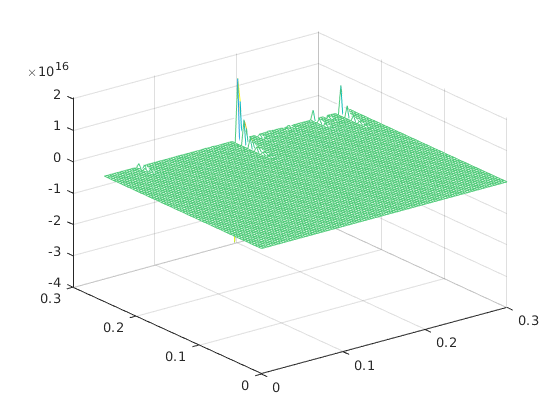

S_0 = 10^4; % 10^4..6 * 1/(um^3 * us)

N = 100;

tspan = [0,0.25];
n_t = 50;
n_y = 100;
ya = zeros(n_y+1,1);
z = linspace(0,0.3,n_y+1);

S_0 = 10^4;
[t1,y1] = impl_trapez(@fd_nonlin_4,tspan,ya,n_t,@fd_nonlin_jac_4,tol,nmax);
S_0 = 10^5;
[t2,y2] = impl_trapez(@fd_nonlin_4,tspan,ya,n_t,@fd_nonlin_jac_4,tol,nmax);
S_0 = 10^6;
[t3,y3] = impl_trapez(@fd_nonlin_4,tspan,ya,n_t,@fd_nonlin_jac_4,tol,nmax);

figure;
mesh(z,t1,y1);
hold on